# DT and RF In-Class Practice: Answer Key

## Load and subset the data

% Load data + display top entries
metab = readtable('karmen_metabolomics.xlsx'); 
head(metab)

ans = 8×443 table
      Sex        Age      Carnitin_LCMS    Betain_LCMS    Cholin_LCMS    DMG_LCMS    Sarcosin_LCMS    TMAO_LCMS      C0       C18_1        C2       Ala       Arg       Asn       Asp       Gln       His       Ile       Leu       Lys       Met       Orn       Phe       Pro       Ser       Thr       Trp       Tyr       Val      Creatinine    Kynurenine    Sarcosine    Serotonine    lysoPC_a_C16_0    

% Create subset table of male participants only
metab_male = metab(strcmp(metab.Sex, 'Male'), :); 

% Create subset table of female participants only
metab_female = metab(strcmp(metab.Sex, 'Female'), :); 

## Predict age for male participants

% Define input and output
X = metab_male(:, 3:end);   % input = metabolites
Y = metab_male.Age;         % output = age

% Split data into training/testing sets via 30% holdout
idx = crossvalind('HoldOut', numel(Y), 0.3); 
[Xtrain, Ytrain, Xtest, Ytest] = deal(X(idx, :), Y(idx), X(~idx, :), Y(~idx)); 

### Decision tree models

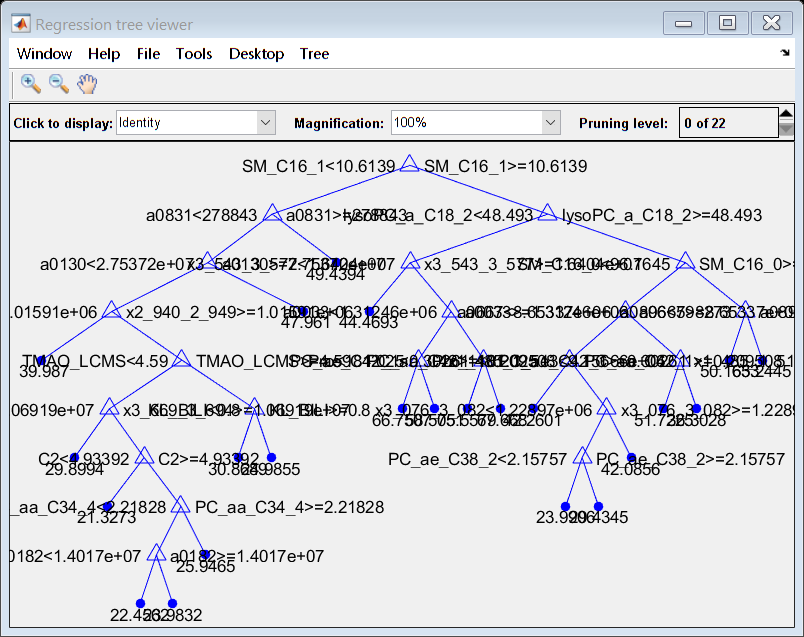

% Build DT model
DT_male = fitrtree(Xtrain, Ytrain); 
% View tree structure graphically
view(DT_male, 'mode', 'graph')

% Assess the resubstitution error
resuberror = resubLoss(DT_male); 
fprintf('The resubstitution classification error is %4.2f \n', resuberror)

The resubstitution classification error is 11.90 


% Assess the cross-validation error
cverror = cvloss(DT_male); 
fprintf('The 10-fold cross-validation error is %4.2f \n', cverror)

The 10-fold cross-validation error is 317.86 


% Determine best prune level via CV error
[~, ~, ~, Best_prune_level] = cvloss(DT_male, 'Subtrees', 'all')

Best_prune_level = 18

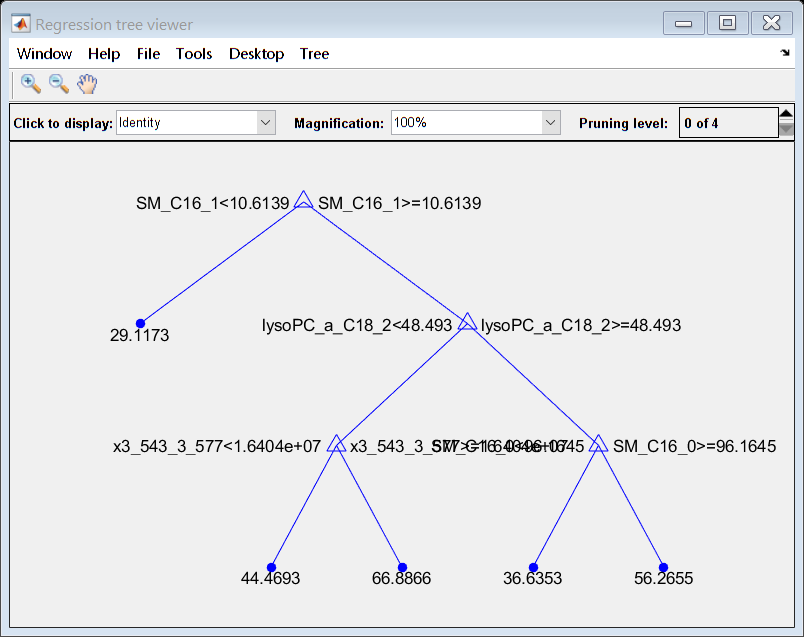

% Build and view pruned tree
DT_male_pruned = prune(DT_male, 'Level', Best_prune_level); 
view(DT_male_pruned, 'Mode', 'Graph')

% Assess the resubstitution error
resuberror = resubLoss(DT_male_pruned); 
fprintf('The resubstitution classification error is %4.2f \n', resuberror)

The resubstitution classification error is 77.03 


% Assess the cross-validation error
cverror = cvloss(DT_male_pruned); 
fprintf('The 10-fold cross-validation error is %4.2f \n', cverror)

The 10-fold cross-validation error is 354.66 


|======================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |      5.4476 |     0.48069 |      5.4476 |      5.4476 |            9 |


|    2 | Best   |      5.4306 |     0.34249 |      5.4306 |      5.4316 |            1 |


|    3 | Accept |      5.4433 |      0.3118 |      5.4306 |      5.4312 |            3 |


|    4 | Accept |      5.4805 |     0.18697 |      5.4306 |      5.4356 |           31 |


|    5 | Accept |      5.4306 |     0.25493 |      5.4306 |      5.4306 |            1 |


|    6 | Best   |      5.4068 |     0.16546 |      5.4068 |      5.4399 |           32 |


|    7 | Accept |      5.7722 |      0.1642 |      5.4068 |      5.4069 |           60 |


|    8 | Accept |      5.4817 |     0.16131 |      5.4068 |      5.4338 |           34 |


|    9 | Accept |      5.5699 |     0.17317 |      5.4068 |      5.4959 |           23 |


|   10 | Accept |      5.5595 |     0.17109 |      5.4068 |      5.5023 |           19 |


|   11 | Accept |      5.5892 |     0.21101 |      5.4068 |      5.5102 |            5 |


|   12 | Accept |      5.4306 |     0.20773 |      5.4068 |      5.5035 |            1 |


|   13 | Accept |      5.4306 |     0.20264 |      5.4068 |      5.4069 |            1 |


|   14 | Accept |       5.429 |     0.16374 |      5.4068 |      5.4069 |           33 |


|   15 | Accept |      5.7673 |     0.17855 |      5.4068 |      5.4069 |           42 |


|   16 | Best   |      5.3605 |     0.17448 |      5.3605 |      5.3605 |           16 |


|   17 | Best   |      5.3509 |     0.20644 |      5.3509 |      5.3509 |           15 |


|   18 | Best   |      5.2577 |     0.18061 |      5.2577 |      5.2577 |           14 |


|   19 | Accept |      5.4018 |     0.17553 |      5.2577 |      5.2577 |           13 |


|   20 | Accept |      5.4031 |     0.20271 |      5.2577 |      5.2577 |            2 |


|======================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|   21 | Accept |      5.5186 |     0.23527 |      5.2577 |      5.2577 |            4 |


|   22 | Accept |      5.3531 |     0.18267 |      5.2577 |      5.3228 |           11 |


|   23 | Accept |      5.2577 |     0.17934 |      5.2577 |      5.2577 |           14 |


|   24 | Accept |      5.3851 |     0.18235 |      5.2577 |      5.2577 |           10 |


|   25 | Accept |      5.4911 |     0.19336 |      5.2577 |      5.2577 |            7 |


|   26 | Accept |      5.4739 |     0.17501 |      5.2577 |      5.3037 |            8 |


|   27 | Accept |      5.2577 |     0.17012 |      5.2577 |      5.2577 |           14 |


|   28 | Accept |      5.5282 |     0.18792 |      5.2577 |      5.2577 |            6 |


|   29 | Accept |      5.7971 |     0.18454 |      5.2577 |      5.2938 |           47 |


|   30 | Accept |       5.537 |     0.16982 |      5.2577 |      5.2938 |           26 |


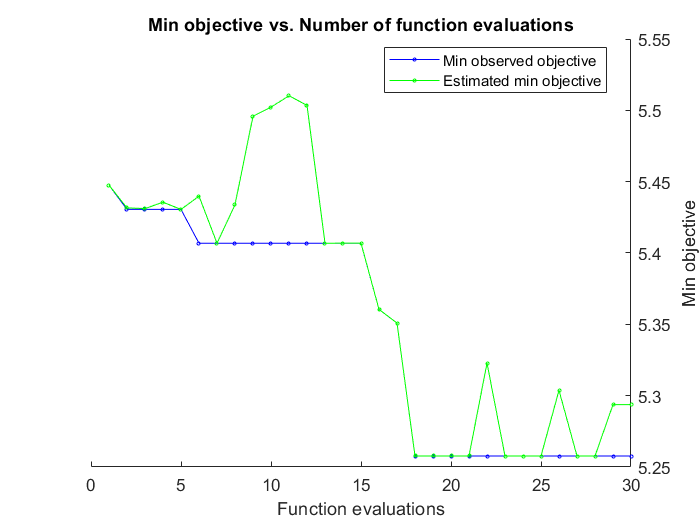

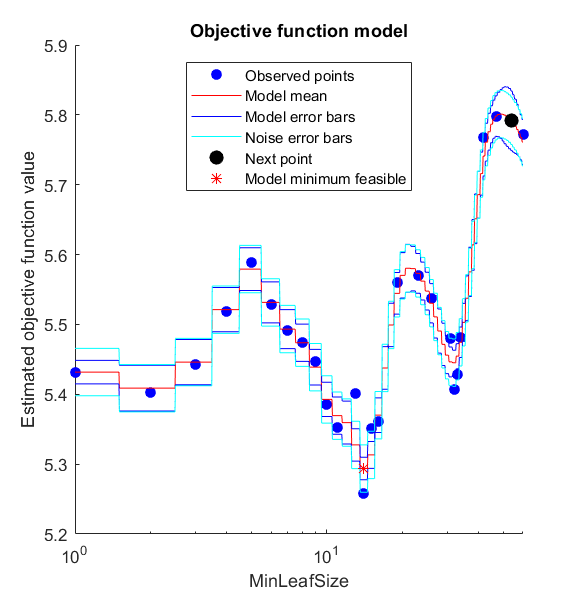


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 46.5924 seconds.
Total objective function evaluation time: 6.1759

Best observed feasible point:
    MinLeafSize
    ___________

        14     

Observed objective function value = 5.2577
Estimated objective function value = 5.2938
Function evaluation time = 0.18061

Best estimated feasible point (according to models):
    MinLeafSize
    ___________

        14     

Estimated objective function value = 5.2938
Estimated function evaluation time = 0.19104



% Build tree with automated hyperparameter tuning
DT_male_auto = fitrtree(Xtrain, Ytrain, 'OptimizeHyperparameters', 'auto'); 

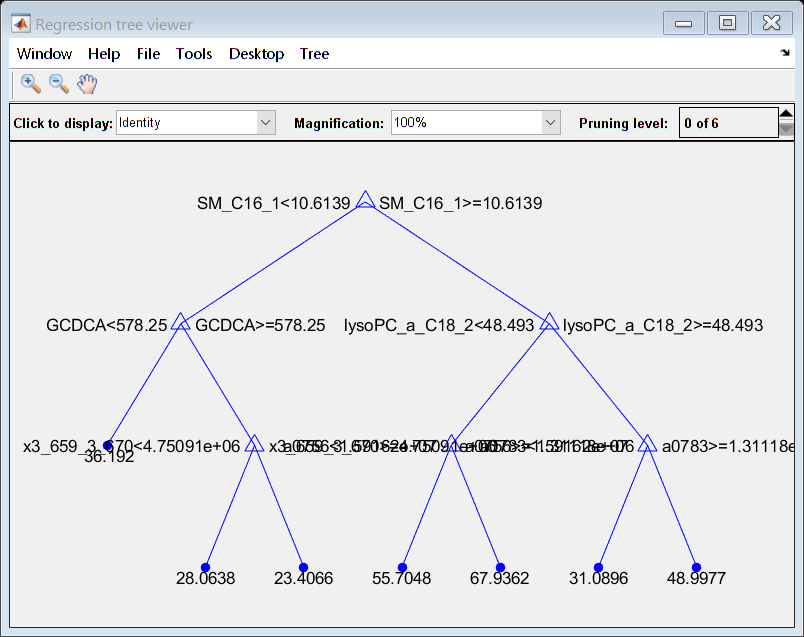

view(DT_male_auto, 'Mode', 'Graph')

% Assess the resubstitution error
resuberror = resubLoss(DT_male_auto); 
fprintf('The resubstitution classification error is %4.2f \n', resuberror)

The resubstitution classification error is 78.50 


% Assess the cross-validation error
cverror = cvloss(DT_male_auto); 
fprintf('The 10-fold cross-validation error is %4.2f \n', cverror)

The 10-fold cross-validation error is 282.66 


Answer: Structurally, the pruned model is the simplest while the initial model is the most complex. All three models share the same base (SM_C16_1) and slightly differ thereafter. In terms of training error, the pruned model does not perform as well as the initial or automated models. 

% Determine predictions using all 3 models
Y1 = predict(DT_male, Xtest); 
Y2 = predict(DT_male_pruned, Xtest); 
Y3 = predict(DT_male_auto, Xtest); 

% Calculate the spearman correlations
[r1, p1] = corr(Ytest, Y1, 'type', 'spearman'); 
[r2, p2] = corr(Ytest, Y2, 'type', 'spearman'); 
[r3, p3] = corr(Ytest, Y3, 'type', 'spearman'); 
fprintf('Initial DT model: R = %4.2f, p = %4.2e \n', r1, p1)

Initial DT model: R = 0.28, p = 4.44e-02 


fprintf('Pruned DT model: R = %4.2f, p = %4.2e \n', r2, p2)

Pruned DT model: R = 0.47, p = 4.89e-04 


fprintf('Automated DT model: R = %4.2f, p = %4.2e \n', r3, p3)

Automated DT model: R = 0.49, p = 2.36e-04 


Answer: The automated DT model yielded the most accurate predictions for the test set. Based on the structure of all three DT models, this does appear to be the optimal model as its structure is neither too simple (pruned) nor too complex (initial), and thus, is more generalizable to new data.

### Random forests models

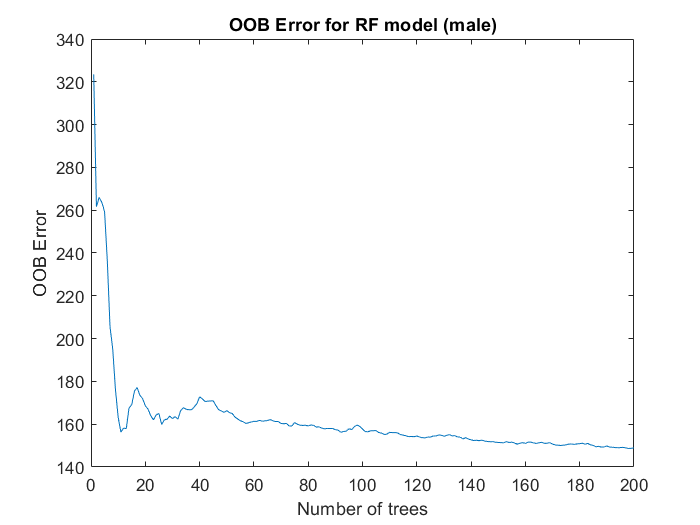

% Build an RF model using TreeBagger
RF_male_tb = TreeBagger(200, Xtrain, Ytrain, 'Method', 'regression', 'OOBPrediction', 'On'); 

% Determine the OOB error as trees are added 
error = oobError(RF_male_tb); 

% Plot OOB error as a function of number of trees
figure
plot(error)
xlabel('Number of trees')
ylabel('OOB Error')
title('OOB Error for RF model (male)')

Answer: From the plot above, it looks like using ~200 trees yields the best RF model (for the range we assessed). 

% Build RF model with optimal number of trees
n = find(error == min(error)); 
RF_male_tb_opt = TreeBagger(n, Xtrain, Ytrain, 'Method', 'regression', 'OOBPredictorImportance', 'On');

% Determine the top 25 important features
mets = readtable('karmen_metabolomics.xlsx', 'Sheet', 'metabolite_key'); % load metabolite info
Importance = RF_male_tb_opt.OOBPermutedPredictorDeltaError';             % extract importance scores
Feature = X.Properties.VariableNames';                                   % extract feature names
[~, ~, idx] = intersect(Feature, mets.Abbreviation, 'stable');           % match metabolites to features
Metabolite = mets.Name(idx);
t_male = table(Feature, Metabolite, Importance);                         % create feature importance table
t_male = sortrows(t_male, 'Importance', 'descend');                      % sort by descending importance
disp(t_male(1:25, :))                                                    % display the top 25 features

         Feature                         Metabolite                    Importance
    __________________    _________________________________________    __________

    {'SM_C16_1'      }    {'Sphingo-myelin C16:1'                 }     0.43216  
    {'x0_937_0_950'  }    {'unknown 0.94'                         }     0.33828  
    {'lysoPC_a_C18_2'}    {'Lyso-phosphatidyl-choline C18:2'      }     0.29913  
    {'KL_CHO'        }    {'Total cholesterol'                    }     0.27585  
    {'a0896'         }    {'Pseudo-uridine TMS5'                  }     0.26964  
    {'SM_C24_0'      }    {'Sphingo-myelin C24:0'                 }     0.26799  
    {'x3_768_3_776'  }    {'unknown 3.77'                         }     0.21189  
    {'x3_924_3_940'  }    {'Glucose 2'                            }     0.21087  
    {'PC_aa_C36_1'   }    {'Diacyl-phosphatidyl-choline C36:1'    }     0.194

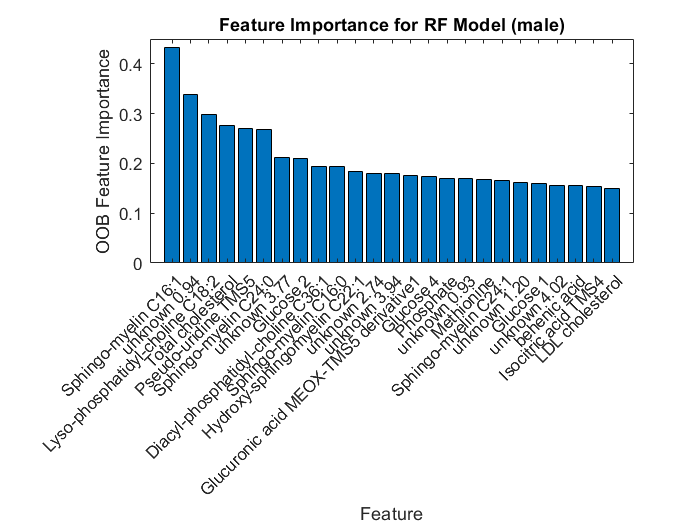

% Visualize importance as a bar plot for the top 25 features
figure
bar(t_male.Importance(1:25))             % plot importance along y-axis
xticks(1:25)                             % allocate tick for each feature
xticklabels(t_male.Metabolite(1:25))     % label ticks with metabolite name
xtickangle(45)                           % rotate x-tick labels
xlabel('Feature')   
ylabel('OOB Feature Importance')
title('Feature Importance for RF Model (male)')

Answer: Many of the identifiable metabolites appear to be lipids (e.g. SM, SM(OH), LPC), with some amino or organic acids detected as well. Many of these metabolites are known to be involved in neural function (lipids, some acids) or disease (e.g. diabetes). 

% Determine predictions for test set
Ypred = predict(RF_male_tb_opt, Xtest); 

% Calculate the spearman correlations
[r, p] = corr(Ytest, Ypred, 'type', 'spearman'); 
fprintf('RF model: R = %4.2f, p = %4.2e \n', r, p)

RF model: R = 0.76, p = 0.00e+00 


Answer: Compared to the DT models, the RF model yielded more accurate predictions for the test set.

## Predict age for female participants

% Define input and output
X = metab_female(:, 3:end);   % input = metabolites
Y = metab_female.Age;         % output = age

% Split data into training/testing sets via 30% holdout
idx = crossvalind('HoldOut', numel(Y), 0.3); 
[Xtrain, Ytrain, Xtest, Ytest] = deal(X(idx, :), Y(idx), X(~idx, :), Y(~idx)); 

### Decision tree models

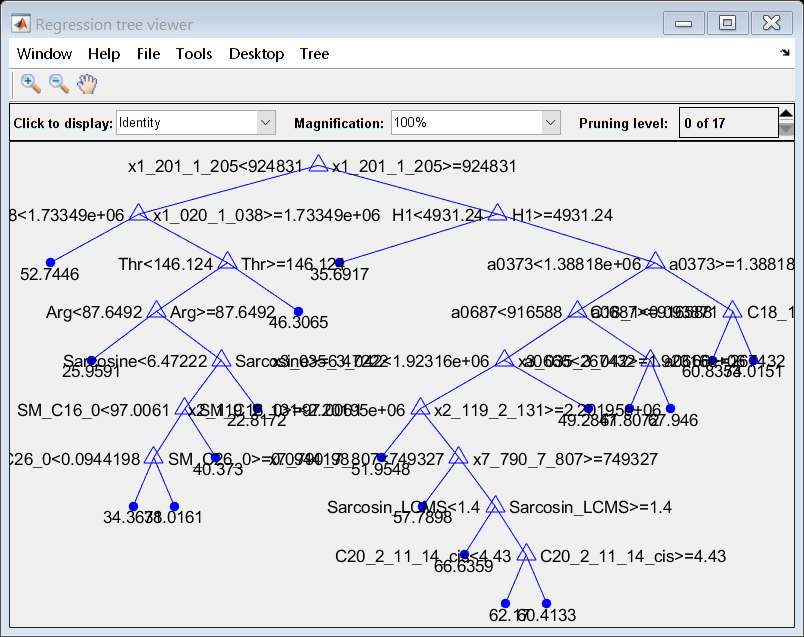

% Build and view initial DT model 
DT_female = fitrtree(Xtrain, Ytrain); 
view(DT_female, 'mode', 'graph')

% Assess the resubstitution error
resuberror = resubLoss(DT_female); 
fprintf('The resubstitution classification error is %4.2f \n', resuberror)

The resubstitution classification error is 18.77 


% Assess the cross-validation error
cverror = cvloss(DT_female); 
fprintf('The 10-fold cross-validation error is %4.2f \n', cverror)

The 10-fold cross-validation error is 242.38 


% Determine best prune level via CV error
[~, ~, ~, Best_prune_level] = cvloss(DT_female, 'Subtrees', 'all')

Best_prune_level = 16

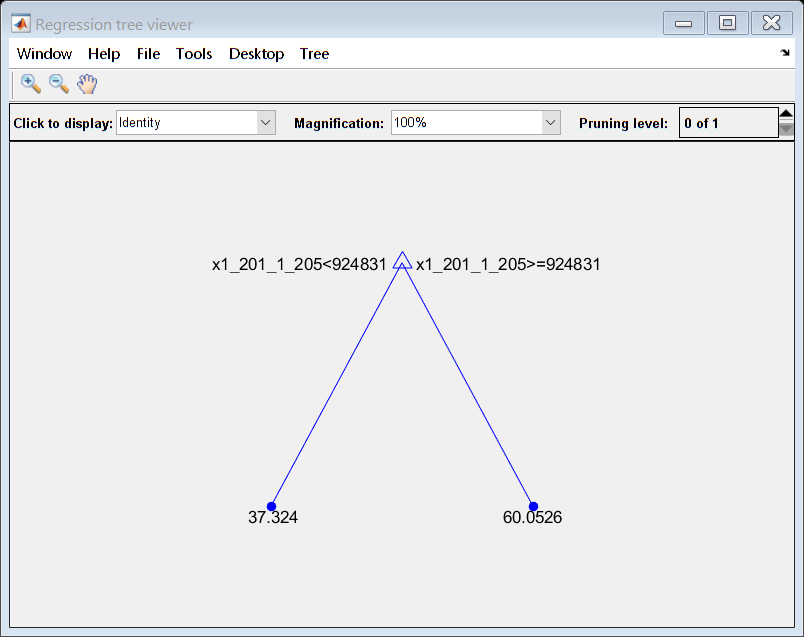

% Build and view pruned model
DT_female_pruned = prune(DT_female, 'Level', Best_prune_level); 
view(DT_female_pruned, 'Mode', 'Graph')

% Assess the resubstitution error
resuberror = resubLoss(DT_female_pruned); 
fprintf('The resubstitution classification error is %4.2f \n', resuberror)

The resubstitution classification error is 122.15 


% Assess the cross-validation error
cverror = cvloss(DT_female_pruned); 
fprintf('The 10-fold cross-validation error is %4.2f \n', cverror)

The 10-fold cross-validation error is 199.58 


|======================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |      5.5526 |     0.24454 |      5.5526 |      5.5526 |            1 |


|    2 | Best   |      5.3481 |     0.16958 |      5.3481 |      5.3588 |           18 |


|    3 | Best   |      5.1534 |     0.15707 |      5.1534 |      5.2659 |           36 |


|    4 | Accept |      5.3936 |     0.16809 |      5.1534 |      5.2454 |            8 |


|    5 | Accept |      5.5284 |     0.17549 |      5.1534 |      5.3952 |           45 |


|    6 | Accept |      5.5147 |     0.18942 |      5.1534 |      5.4151 |            3 |


|    7 | Accept |      5.5526 |     0.20566 |      5.1534 |      5.4153 |            1 |


|    8 | Best   |      5.0778 |     0.19814 |      5.0778 |      5.0779 |           25 |


|    9 | Accept |      5.2132 |     0.16078 |      5.0778 |      5.0779 |           35 |


|   10 | Accept |      5.0778 |     0.18218 |      5.0778 |      5.0778 |           26 |


|   11 | Accept |      5.3054 |     0.18875 |      5.0778 |      5.0778 |           23 |


|   12 | Accept |      5.0905 |     0.23026 |      5.0778 |      5.0778 |           28 |


|   13 | Accept |      5.2264 |     0.16485 |      5.0778 |       5.136 |           27 |


|   14 | Accept |      5.1016 |     0.18105 |      5.0778 |      5.1214 |           30 |


|   15 | Accept |      5.1016 |      0.1605 |      5.0778 |      5.1168 |           30 |


|   16 | Accept |      5.1016 |     0.16371 |      5.0778 |      5.1107 |           30 |


|   17 | Accept |      5.2584 |     0.17006 |      5.0778 |      5.1139 |           12 |


|   18 | Accept |      5.5363 |     0.17586 |      5.0778 |      5.1109 |            5 |


|   19 | Accept |      5.5854 |     0.21668 |      5.0778 |      5.1115 |            2 |


|   20 | Accept |      5.5243 |     0.18385 |      5.0778 |       5.112 |            4 |


|======================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|   21 | Accept |      5.2936 |     0.16017 |      5.0778 |      5.1117 |           15 |


|   22 | Accept |      5.3796 |     0.20428 |      5.0778 |      5.1121 |           10 |


|   23 | Accept |      5.4058 |     0.17765 |      5.0778 |      5.1121 |            6 |


|   24 | Accept |      5.4127 |     0.18437 |      5.0778 |      5.1116 |            7 |


|   25 | Accept |      5.5284 |     0.16234 |      5.0778 |       5.114 |           40 |


|   26 | Accept |      5.2558 |     0.16266 |      5.0778 |      5.1131 |           13 |


|   27 | Accept |      5.3649 |     0.17828 |      5.0778 |      5.1128 |            9 |


|   28 | Accept |      5.3479 |     0.16487 |      5.0778 |      5.1118 |           20 |


|   29 | Accept |      5.0778 |     0.17811 |      5.0778 |      5.1047 |           25 |


|   30 | Accept |       5.353 |     0.16258 |      5.0778 |      5.1045 |           11 |


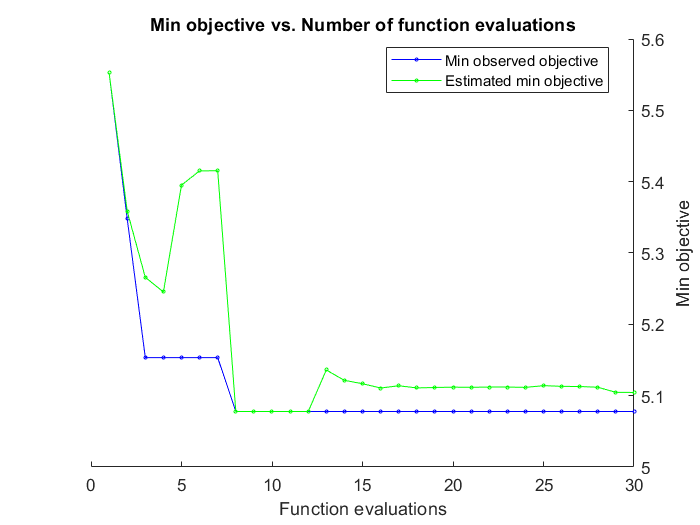

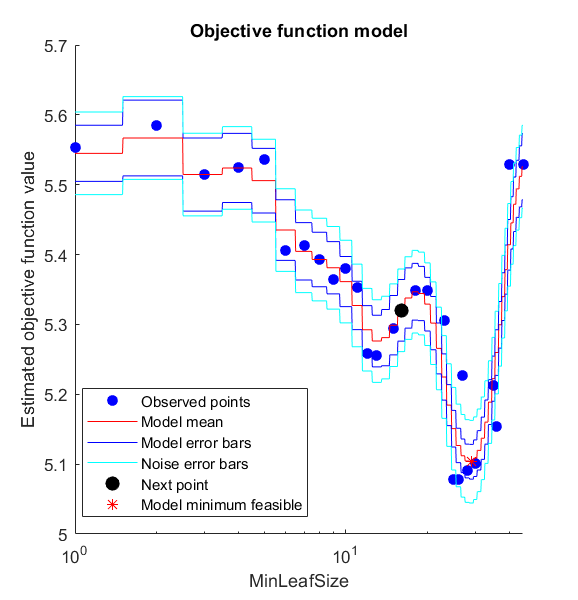


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 47.954 seconds.
Total objective function evaluation time: 5.4218

Best observed feasible point:
    MinLeafSize
    ___________

        25     

Observed objective function value = 5.0778
Estimated objective function value = 5.1508
Function evaluation time = 0.19814

Best estimated feasible point (according to models):
    MinLeafSize
    ___________

        28     

Estimated objective function value = 5.1045
Estimated function evaluation time = 0.17415



% Build and view model with automated hyperparameter tuning
DT_female_auto = fitrtree(Xtrain, Ytrain, 'OptimizeHyperparameters', 'auto'); 

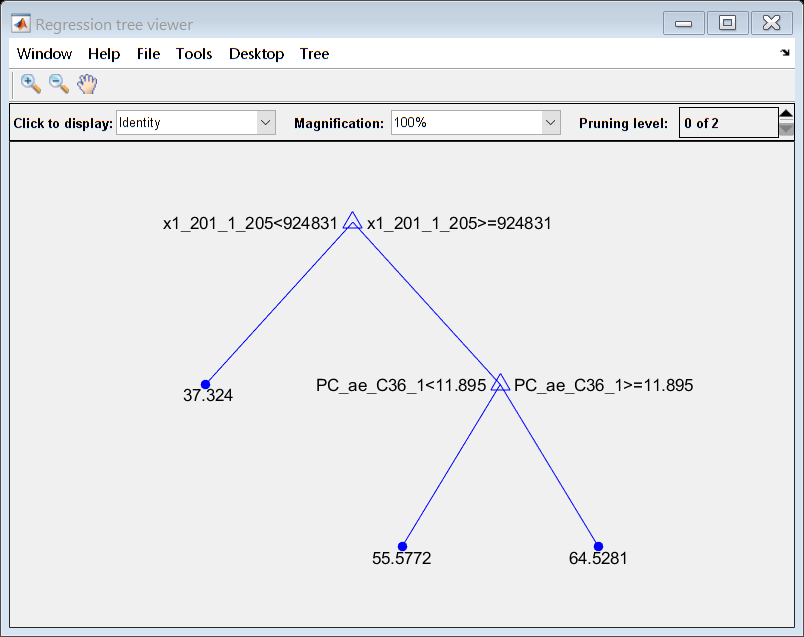

view(DT_female_auto, 'Mode', 'Graph')

% Assess the resubstitution error
resuberror = resubLoss(DT_female_auto); 
fprintf('The resubstitution classification error is %4.2f \n', resuberror)

The resubstitution classification error is 109.38 


% Assess the cross-validation error
cverror = cvloss(DT_female_auto); 
fprintf('The 10-fold cross-validation error is %4.2f \n', cverror)

The 10-fold cross-validation error is 156.28 


Answer: Similar to the male DT models, the pruned model is structurally simplest while the initial model is most complex. All three models also share the same base (x1_201_1_205) and differ thereafter. In terms of training error, the pruned and automated models perform better than the initial model w.r.t. CV error, but perform worse w.r.t. the resubstitution error. 

% Determine predictions using all 3 models
Y1 = predict(DT_female, Xtest); 
Y2 = predict(DT_female_pruned, Xtest); 
Y3 = predict(DT_female_auto, Xtest); 

% Calculate the spearman correlations
[r1, p1] = corr(Ytest, Y1, 'type', 'spearman'); 
[r2, p2] = corr(Ytest, Y2, 'type', 'spearman'); 
[r3, p3] = corr(Ytest, Y3, 'type', 'spearman'); 
fprintf('Initial DT model: R = %4.2f, p = %4.2e \n', r1, p1)

Initial DT model: R = 0.53, p = 7.09e-04 


fprintf('Pruned DT model: R = %4.2f, p = %4.2e \n', r2, p2)

Pruned DT model: R = 0.63, p = 1.90e-05 


fprintf('Automated DT model: R = %4.2f, p = %4.2e \n', r3, p3)

Automated DT model: R = 0.71, p = 5.59e-07 


Answer: Similar to the male DT models, the automated model yielded the best predictions for the test set. Structurally, it also offers a good compromise between simple and complex.

### Random forests models

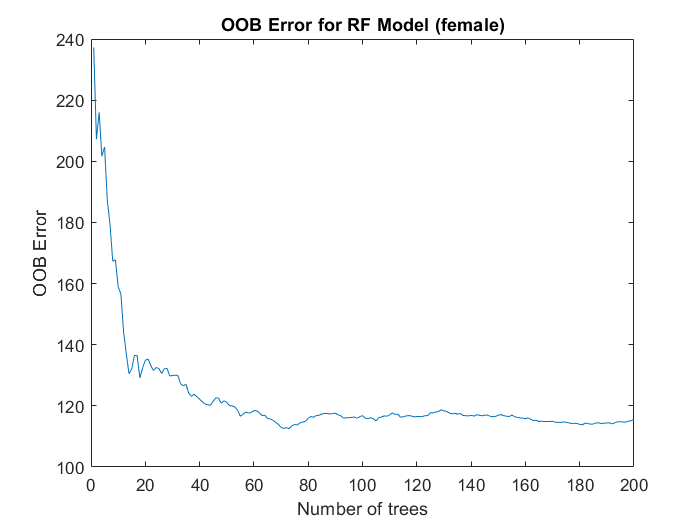

% Build an RF model using TreeBagger
RF_female_tb = TreeBagger(200, Xtrain, Ytrain, 'Method', 'regression', 'OOBPrediction', 'On'); 

% Determine the OOB error as trees are added 
error = oobError(RF_female_tb); 

% Plot OOB error as a function of number of trees
figure
plot(error)
xlabel('Number of trees')
ylabel('OOB Error')
title('OOB Error for RF Model (female)')

% Build RF model with optimal number of trees
n = find(error == min(error)); 
RF_female_tb_opt = TreeBagger(n, Xtrain, Ytrain, 'Method', 'regression', 'OOBPredictorImportance', 'On');

% Determine the top 25 important features
Importance = RF_female_tb_opt.OOBPermutedPredictorDeltaError';  % extract importance scores
Feature = X.Properties.VariableNames';                          % extract feature names
[~, ~, idx] = intersect(Feature, mets.Abbreviation, 'stable');  % match metabolites to features
Metabolite = mets.Name(idx);
t_female = table(Feature, Metabolite, Importance);              % create feature importance table
t_female = sortrows(t_female, 'Importance', 'descend');         % sort by descending importance
disp(t_female(1:25, :))                                         % display the top 25 features

         Feature                        Metabolite                    Importance
    _________________    _________________________________________    __________

    {'x1_201_1_205' }    {'unknown 1.20'                         }     0.34388  
    {'a0896'        }    {'Pseudo-uridine TMS5'                  }     0.29035  
    {'a0585'        }    {'Isocitric acid TMS4'                  }     0.27256  
    {'x0_937_0_950' }    {'unknown 0.94'                         }     0.27068  
    {'a0783'        }    {'Unknown 0783 (sugar or sugar-like)'   }     0.26632  
    {'x2_741_2_749' }    {'unknown 2.74'                         }     0.25436  
    {'x4_020_4_042' }    {'unknown 4.02'                         }     0.25365  
    {'KL_CHO'       }    {'Total cholesterol'                    }     0.23497  
    {'a0142'        }    {'Similar to ethanol-amine TMS3'        }     0.22318  
    {'

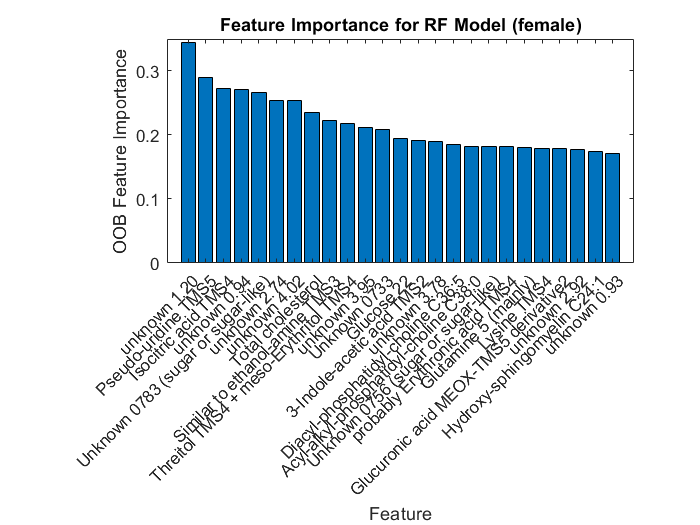

% Visualize importance as a bar plot for the top 25 features
figure
bar(t_female.Importance(1:25))             % plot importance along y-axis
xticks(1:25)                               % allocate tick for each feature
xticklabels(t_female.Metabolite(1:25))     % labels ticks with feature name
xtickangle(45)                             % rotate x-tick labels
xlabel('Feature')
ylabel('OOB Feature Importance')
title('Feature Importance for RF Model (female)')

Answer: Similar to the male RF model, many of the top identifiable metabolites are lipids or amino/organic acids. Interestingly, glucose is not as strong of an indicator for age in women compared to what the male models showed. 

% Determine predictions for test set
Ypred = predict(RF_female_tb_opt, Xtest); 

% Calculate the spearman correlations
[r, p] = corr(Ytest, Ypred, 'type', 'spearman'); 
fprintf('RF model: R = %4.2f, p = %4.2e \n', r, p)

RF model: R = 0.74, p = 6.04e-07 


Answer: Compared to the best DT model (automated), the RF model provides a slight improvement.

## Compare the top 25 predictive features between RF models

% Find any overlapping features that were important in both male and female
% RF models
[Feature, idx1, idx2] = intersect(t_male.Feature(1:25), t_female.Feature(1:25));    % find overlaps
[~, ~, idx] = intersect(Feature, mets.Abbreviation, 'stable');                      % match to metabolite
Metabolite = mets.Name(idx); 
[Imp_male, Imp_female] = deal(t_male.Importance(idx1), t_female.Importance(idx2));  % extract importance
t_overlap = table(Feature, Metabolite, Imp_male, Imp_female);                       % create overlap table
disp(t_overlap)

        Feature               Metabolite           Imp_male    Imp_female
    ________________    _______________________    ________    __________

    {'KL_CHO'      }    {'Total cholesterol'  }    0.27585      0.23497  
    {'a0585'       }    {'Isocitric acid TMS4'}    0.15449      0.27256  
    {'a0896'       }    {'Pseudo-uridine TMS5'}    0.26964      0.29035  
    {'x0_929_0_938'}    {'unknown 0.93'       }     0.1695      0.17166  
    {'x0_937_0_950'}    {'unknown 0.94'       }    0.33828      0.27068  
    {'x1_201_1_205'}    {'unknown 1.20'       }     0.1612      0.34388  
    {'x2_741_2_749'}    {'unknown 2.74'       }    0.18016      0.25436  
    {'x4_020_4_042'}    {'unknown 4.02'       }     0.1553      0.25365  



Answer: Interestingly, none of the top predictive lipids overlapped between the RF models, and only the following 3 intersected between the two models: total cholesterol, isocitric acid, and pseudouridine. Upon quick literature search, there does not seem to be a clear connection between plasma level of these metabolites and aging.

Answer: Based on the identifiable and overlapping entriles listed above, only cholesterol appears to make intuitive sense. Abnormal cholesterol levels are associated with various diseases (e.g. diabetes, CVD), many of which are more prevalent with older age. The other identified and overlapping metabolites may also be indicative of age progression, but literature evidence is needed to support this idea.